# Experimental Fluids Lab #2

**Import Data Sets**

% %% (1) Import Kulite Data (PC)
% kdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #2\Lab2_Kulite4\';
% files3 = dir([kdir,'test*.mat']);
% N3 = length(files3);
% for p = 1:N3
% [~,f1] = fileparts(files3(p).name);
% file_name = [kdir,f1,'.mat'];
% load(file_name,'timeseries_data');
% k1(p) = mean(timeseries_data(:,1)); % kulite #1 voltages
% k2(p) = mean(timeseries_data(:,2)); % kulite #2 voltages
% end

% Import Kulite Data (Mac OS)
kdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #2/Lab2_Data_Group2/Lab2_Kulite4/';
files3 = dir([kdir,'test*.mat']);
N3 = length(files3);
for p = 1:N3
[~,f1] = fileparts(files3(p).name);
file_name = [kdir,f1,'.mat'];
load(file_name,'timeseries_data');
k1(p) = mean(timeseries_data(:,1)); % kulite #1 voltages
k2(p) = mean(timeseries_data(:,2)); % kulite #2 voltages
end

%% (2) Import Desired Pitot Data (PC)

%file_name = [XXX_YYY]
% XXX = 'pre', 'post', or 'no_flow'
% YYY = 'upstream, 'downstream', or 'upstream_downstream'


% pdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #2\Lab2_Pitot\';
% load([pdir 'XXX_YYY.mat']);
% P = mean(timeseries_data); % rename this variable to coincide with each XXX_YYY variation

% Import Pitot Data (Mac OS)
pdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #2/Lab2_Data_Group2/Lab2_Pitot/';
load([pdir 'post_upstream_downstream.mat']);
P_postupdown = mean(timeseries_data); % rename this variable to coincide with each XXX_YYY variation


% %% (3) Import Hote-Wire Calibration Data (PC)
% cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #2\';
% LISTING = dir([cdir,'Lab2_Calib\test*.mat']);
% [~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
% LISTING=LISTING(idx);
% for hh =1:length(LISTING)
%     [~,filelead] = fileparts(LISTING(hh).name);
%     load([cdir,'Lab2_Calib\',filelead,'.mat'])
%     setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
%     cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
% end

% % Import Hot-Wire Calibration Data (Mac OS)
cdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #2/Lab2_Data_Group2/';
LISTING = dir([cdir,'Lab2_Calib/test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Lab2_Calib/',filelead,'.mat'])
    setra(hh) = mean(timeseries_data(:,1))'; % pressure xdcr voltages
    cta(hh) = mean(timeseries_data(:,2))';% anemometer voltages
end


% (4) Import Experimental Data

% % Import Lab Data (PC)
% cdir = 'C:\Users\dlawson6\Desktop\Raw Lab Data\Experimental Methods Lab #2\';
% LISTING = dir([cdir,'Lab2_HotWire\test*.mat']);
% [~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
% LISTING=LISTING(idx);
% for hh =1:length(LISTING)
%     [~,filelead] = fileparts(LISTING(hh).name);
%     load([cdir,'Lab2_HotWire\',filelead,'.mat'])
%     E(:,hh)=timeseries_data(:,2)'; % anemometer voltages
% end
% y = readmatrix([cdir,'step_list']);y=y(:,4); From lab1, necessary?

% Import Lab Data (Mac OS)
cdir = '/Users/dan/Desktop/Lab Data/Experimental Fluids Lab #2/Lab2_Data_Group2/';
LISTING = dir([cdir,'Lab2_HotWire/test*.mat']);
[~,idx] = sort(cellfun(@(x) x,{LISTING(:).date},'UniformOutput',false));
LISTING=LISTING(idx);
for hh =1:length(LISTING)
    [~,filelead] = fileparts(LISTING(hh).name);
    load([cdir,'Lab2_HotWire/',filelead,'.mat'])
    E(:,hh)=timeseries_data(:,2)'; % anemometer voltages
end
% %y = readmatrix([cdir,'step_list']);y=y(:,4); From lab1, necessary?


**Hot-Wire Calibration**

% Conditions and Initialization

% First load Hot-Wire and Pitot Calibration data from (3) above

freq_f =  [0, 6, 10, 15, 20, 25, 30, 35]; % fan frequency (Hz)
T_s = 10; % time (s)
freq_s = 10000; % Sample Frequency (Hz)
Cal_factor = 67.82; % Pressure Transducer Calibration: 67.82 [Pa/V]
Pvol_cal = abs(setra - setra(1)); % Zeroed Pressure transducer voltages for calibration (V)
P_Pitot = Cal_factor * Pvol_cal; % Pitot tube pressure readings (Pa)

P_amb1 = 999 * 100; % Ambient pressure at the start of lab, convert from millibar -> Pa, (Pa)
P_amb2 = 999 * 100; % Ambient pressure at the end of lab (same as start), convert from millibar -> Pa, (Pa)
T_amb1 = 24.1 + 273; % Ambient Temperature at start of lab, convert from centigrade -> Kelvin (K)
T_amb2 = 22.8 + 273; % Ambient Temperature at end of lab, convert from centigrade -> Kelvin (K)
R = 287; % Gas constant for air (J / Kg *K)


% Convert differntial pressure readings into velocities using Bernoulli's

rho1 = P_amb1 / (R * T_amb1); % Incompressible air density at start of lab (kg/m^)

for ii = 1:length(P_Pitot)

U_pitot(ii) = sqrt(2 * abs(P_Pitot(ii)) / rho1); % Air velocities from pitot tube measuremnt (m/s)

end

% Determine the total relative errors in velocity calibration from
% pressure/temperature sensors and pressure transducer

% Input and calculate device acccuracies and sources of uncertainty 

acc_P_amb = 4 * 100; % +/- Accuracy of ambient pressure measurement, converts from mBar to Pa (Pa)
acc_T_amb = 0.4; % +/- Accuracy of ambient temperature measurement (K)
acc_Tran = (0.5/100) * 550; % Accuracy of pressure transducer, converted from relative to Pa via Full-Scale (Pa)

res_P_amb = 1 * 100; % Resolution of ambient pressure measurement, converts from mBar to Pa (Pa)
res_T_amb = 0.1; % Resolution of ambient temperature measurement (K)

drift_T_amb = (T_amb1 - T_amb2) / 2; % drift error of initial and end ambient temperature (K)

% Calculate relative errors
rho_bar = ((P_amb1 / (R * T_amb1)) + (P_amb2 / (R * T_amb2))) / 2; % Mean of air density from start and end of lab (kg / m^3)

err_P_amb = sqrt(acc_P_amb^2 + res_P_amb^2); % Absolute error for ambient pressure measurement (Pa)
err_T_amb = sqrt(acc_T_amb^2 + res_T_amb^2 + drift_T_amb^2); % Absolute error for ambient temperature measurement (K)
err_Tran = acc_Tran; % Absolute error of pressure transducer, equal to its accuracy (Pa)
err_rho = sqrt((err_T_amb / (0.5 * (T_amb1 + T_amb2)))^2 + (err_P_amb / (0.5 * (P_amb1 + P_amb2)))^2); % Absolute error of air density, (Kg / m^3)

err_U_pitot = [];


% Calculate and display relative errors of each Pitot Velocity Measurement

for j = 1:length(U_pitot)

    err_U_pitot(j) = 100 * sqrt((0.5 * (err_Tran / P_Pitot(j)))^2 + (0.5 * (err_rho / rho_bar))^2);

end

% Create a 3rd order Polynomial fit to calibrate the hot-wire

Avol_cal = cta; % create seperate array that contains hotwire calibration voltages
X = linspace(Avol_cal(8),Avol_cal(1),1e3); % smoothing array for clean polynomial fit

% Create fit
p3 = polyfit(Avol_cal, U_pitot, 3);

% Display fit Coefficients
fprintf('3rd order Fit Coefficients')

3rd order Fit Coefficients

A = p3(1)

A = -0.0041

B = p3(2)

B = 0.1233

C = p3(3)

C = -1.5520

D = p3(4)

D = 7.2254


y_fit3 = polyval(p3, X);

y_cfit3 = polyval(p3, Avol_cal);


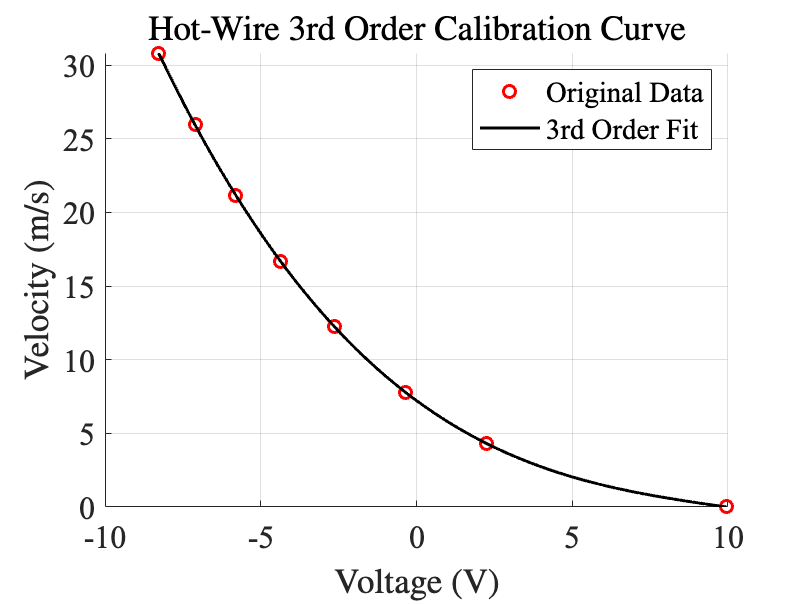

% Plot 3rd order Calibration Curve
figure;
hold on;

plot(Avol_cal, U_pitot, 'ro', 'DisplayName', 'Original Data');
plot(X, y_fit3, 'k-', 'DisplayName', '3rd Order Fit');

hold off;

xlabel('Voltage (V)');
ylabel('Velocity (m/s)');
title('Hot-Wire 3rd Order Calibration Curve');
legend('show','Location','northeast');
grid on

**Mean Velocity Profile and Fluctuation of the Wake**

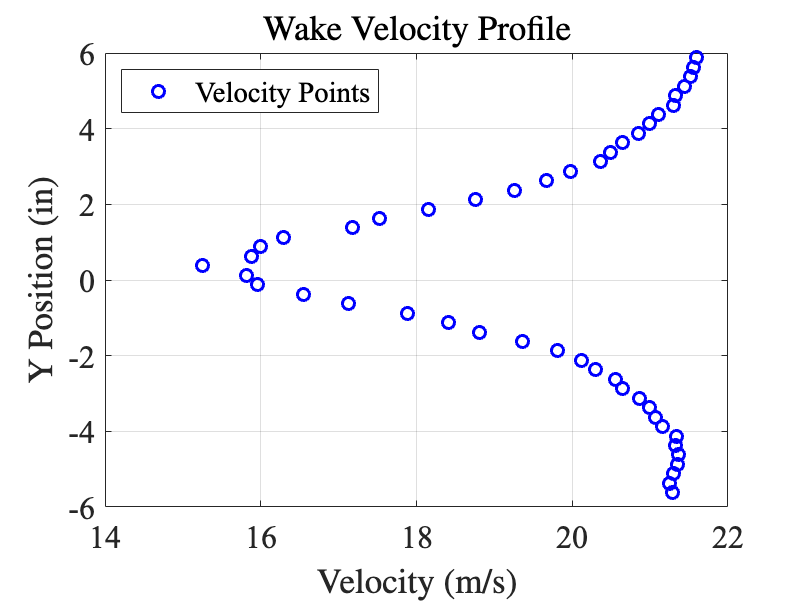

% First load Experimental Hot-Wire data for the Wake from (4) above

% Compute and Plot Velocity profile in the Cylinder Wake

Wake_V = mean(E); % Average Voltages from hot wire in wake behind cylinder (V)

Wake_Y = -5.625:0.25:5.875; % y-values with cylinder center as zero in 1/4 inch steps.
                            % Note that because we only have 47 velocity measurements, we must drop the bottom one to make the vector lengths the same

Wake_U = polyval(p3,Wake_V); % Velocity wake behind the cylinder (m/s)

plot(Wake_U, Wake_Y, 'bo','DisplayName', 'Velocity Points')
xlabel('Velocity (m/s)');
ylabel('Y Position (in)');
title('Wake Velocity Profile');
legend('show','Location','northwest');
grid on

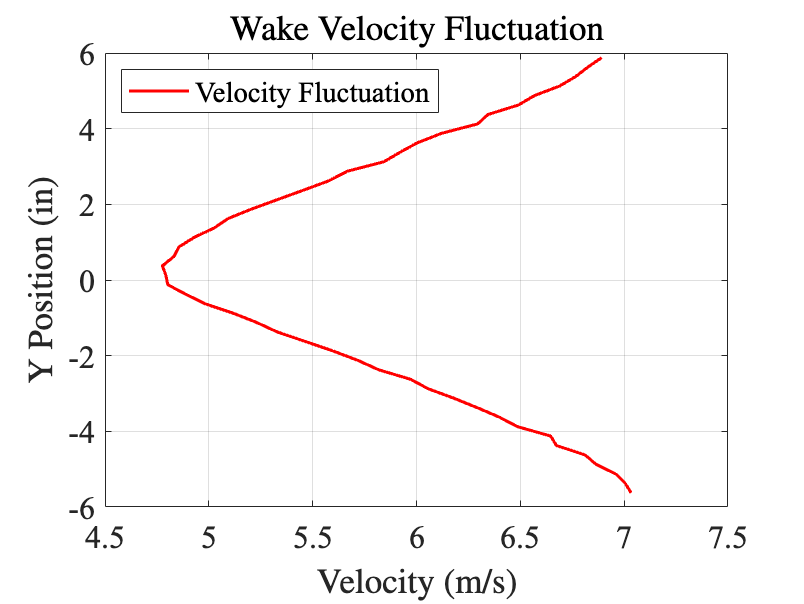


% Compute and Plot the Fluctuation of the Velocity Profile

E_std = std(E); % Take standard deviations of each measurements column

Wake_fluc = polyval(p3,E_std); % Convert vector of STDs into velocity fluctuation vector

plot(Wake_fluc, Wake_Y, 'r-','DisplayName', 'Velocity Fluctuation')
xlabel('Velocity (m/s)');
ylabel('Y Position (in)');
title('Wake Velocity Fluctuation');
legend('show','Location','northwest');
grid on

**Normalize both Profiles**

% To Normalize the Velocity and Fluctuation profiles, U_inf must be
% calculated using conservation of mass and extending the wake profile to the end of the tunnel

% First load 'pre' and 'post' downstream and upstream pitot tube data from (2)

Pitot_downV = (P_predown(1) + P_postdown(1)) / 2; % Average Downstream Pitot voltages (V)

Pitot_down = Pitot_downV * Cal_factor; % Convert to pressure (Pa)

Pitot_upV = (P_preup(1) + P_postup(1)) / 2; % Average Upstream Pitot voltages (V)

Pitot_up = Pitot_upV * Cal_factor; % Convert to pressure (Pa)

% Convert dynamic pressure to velocity

U_down = sqrt(2 * abs(Pitot_down) / rho_bar); % Bernoulli's equation (m/s)

U_up = sqrt(2 * abs(Pitot_up) / rho_bar); % Bernoulli's equation (m/s)

% Use U_down to extend the Wake velocity profile

height = -12:0.25:12; % total height of tunnel (24 in) in 1/4 inch increments with centerline zero

U_Wakeends = U_down * ones(1,25);

Wake_Utot = [U_Wakeends,Wake_U,U_Wakeends];


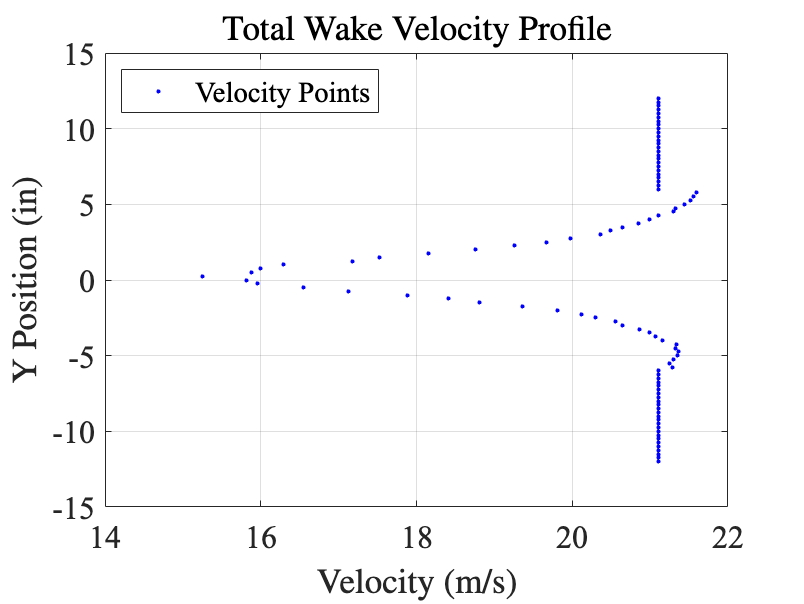

% Plot total velocity wake profile

plot(Wake_Utot, height, 'b.','DisplayName', 'Velocity Points')
xlabel('Velocity (m/s)');
ylabel('Y Position (in)');
title('Total Wake Velocity Profile');
legend('show','Location','northwest');
grid on

% Use conservation of mass to compute U_inf
% U_inf * L = int 0|L (U(y) *dy) where U(y) is the velocity wake profile
% and dy is the change in height

% convert units

dy = 0.25 * 0.0254; % convert vertical stepping to meters (m)

h = 24 * 0.0254; % convert total height to meters

% rearrange and solve for U_inf

U_inf = (sum(Wake_Utot) * dy) / h;


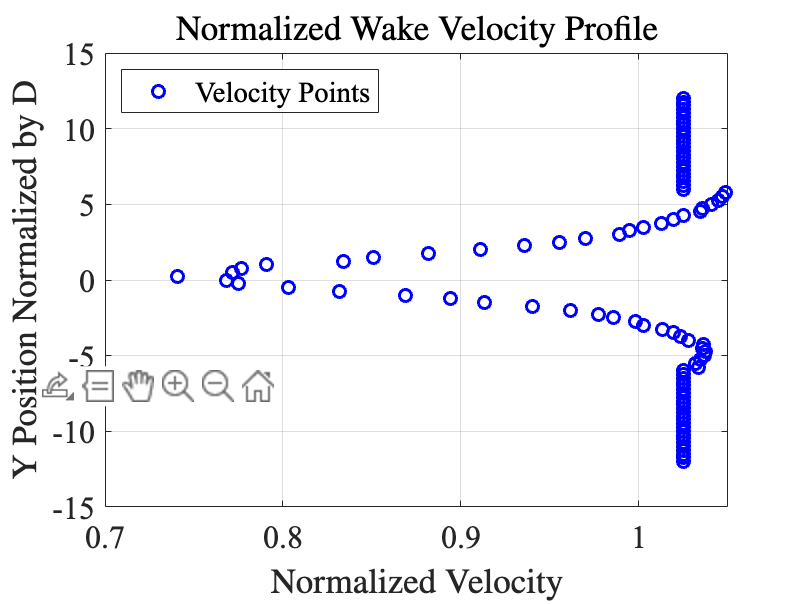

% Now using U_inf and cylinder diameter, replot the normalized wake and fluctuation velocity profiles

D = 2; % cylinder diameter (in)

Wake_Unorm = Wake_Utot / U_inf; % normalized Velocity wake behind the cylinder (dimensionless)
Wake_Ynorm = Wake_Y / D; % normalized height profile

plot(Wake_Unorm, height, 'bo','DisplayName', 'Velocity Points')
xlabel('Normalized Velocity');
ylabel('Y Position Normalized by D');
title('Normalized Wake Velocity Profile');
legend('show','Location','northwest');
grid on

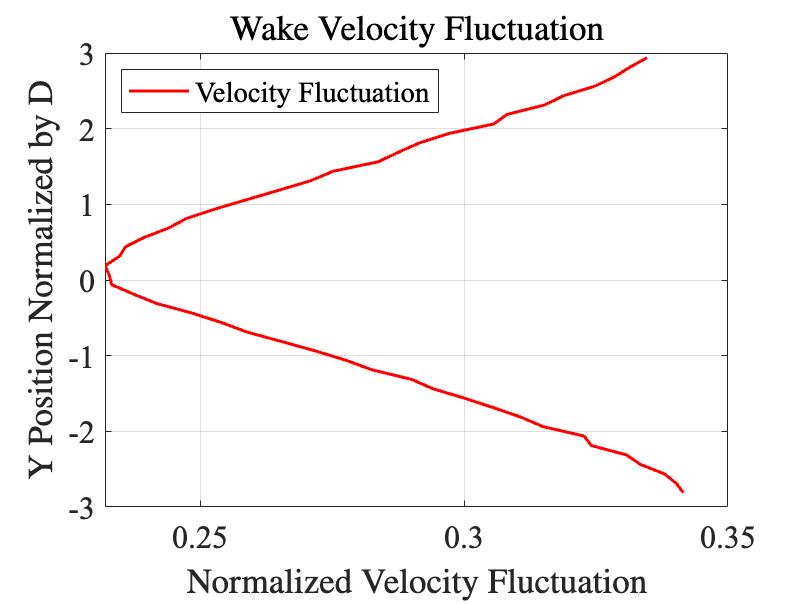


% Compute and Plot the Normalized Fluctuation of the Velocity Profile

Wake_flucnorm = Wake_fluc / U_inf; % normalized velocity fluctuation

plot(Wake_flucnorm, Wake_Ynorm, 'r-','DisplayName', 'Velocity Fluctuation')
xlabel('Normalized Velocity Fluctuation');
ylabel('Y Position Normalized by D');
title('Wake Velocity Fluctuation');
legend('show','Location','northwest');
grid on

**Compute Total Drag and Cd**

% Use the control volume method to compute drag
% Drag = (p1 - p2)*L + rho int 0|L (U(y)*[Uinf -U(y)] *dy)

% First load 'pre' and 'post' downstream_upstream pitot tube data from (2)

Pitot_updownV = (P_preupdown(1) + P_postupdown(1)) / 2; % Average Downstream Pitot voltages (V)

Pitot_updown = Pitot_updownV * Cal_factor; % Convert to pressure (Pa)

% compute Drag

Drag_int = sum(Wake_Utot.*(U_inf - Wake_Utot)) * dy;

Drag = h*(abs(Pitot_updown)) + rho_bar*Drag_int

Drag = 17.2253


% compute the Coeffecient of Drag, Cd

d = D * 0.0254; % convert cylinder diameter to meters

Cd = Drag / (0.5*(rho_bar * d * U_inf^2))

Cd = 1.3620

**Calculate and plot Cp profiles against azimuthal angle**

% First load Kulite4 data from (1) and manually load the 'pre/post_no_flow.mat' file

% convert Kulite voltages into pressure differences

Kul_factor = (6894.76 * 10) / 0.0102; % converts Kulite voltage readings to Pascals when multiplied

k1_bias = (mean(post_no_timeseries_data(:,1)) + mean(pre_no_timeseries_data(:,1))) / 2; % (V)
k2_bias = (mean(post_no_timeseries_data(:,2)) + mean(pre_no_timeseries_data(:,2))) / 2; % (V)

k1_p = (k1 - k1_bias) * Kul_factor; % Pressures from Kulite 1 (Pa)
k2_p = (k2 - k2_bias) * Kul_factor; % Pressures from Kulite 2 (Pa)

k2_p_shift = [k2_p(17:36),k2_p(1:16)]; % shift Kulite pressure to match periodically


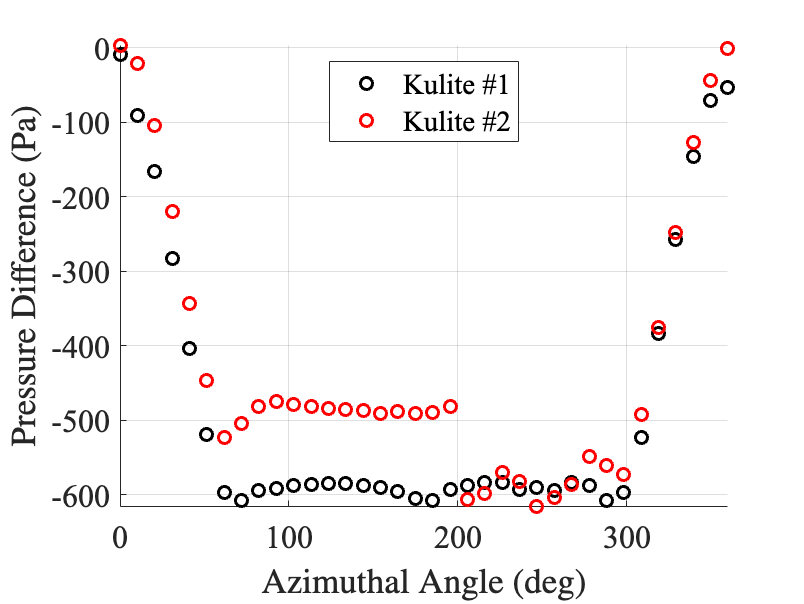

% Plot Cp Profiles against Azimuthal Angle in degrees
thetas = linspace(0,360,36);

figure
hold on

plot(thetas, k1_p, 'ko','DisplayName','Kulite #1')
plot(thetas, k2_p_shift, 'ro','DisplayName','Kulite #2')

xlabel('Azimuthal Angle (deg)')
ylabel('Pressure Difference (Pa)')
xlim([0 360])
legend('show','Location','north');
grid on

% convert pressures into velocities using bernoulli's

for jj = 1:length(k1)

U_k1(jj) = sqrt(2 * abs(k1_p(jj)) / rho_bar); % Air velocities from Kulite 1  measurement (m/s)

U_k2(jj) = sqrt(2 * abs(k2_p(jj)) / rho_bar); % Air velocities from pitot tube measurement (m/s)

end

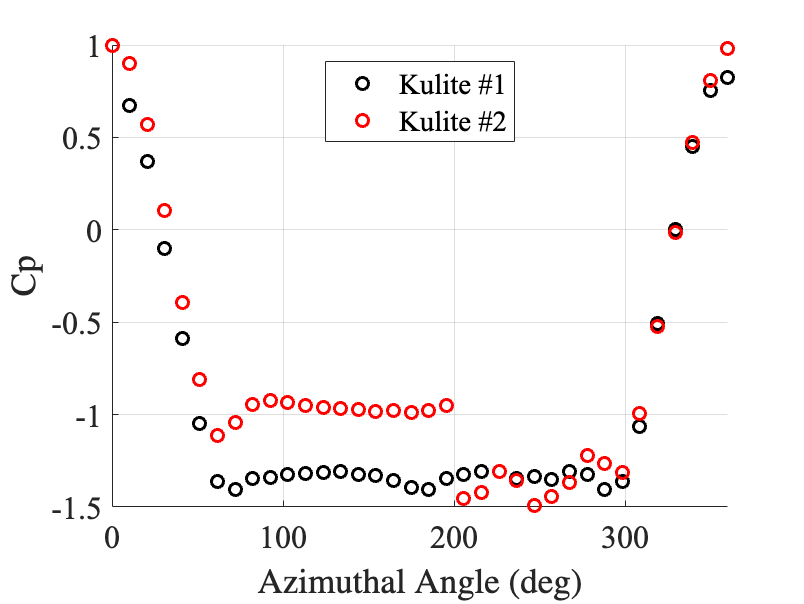

% Calculate Cp arrays
% Cp(theta) = (p - p_inf) / (0.5 * rho * U^2), add 1 to adjust to ambient

Cp_k1 = 1 + (k1_p - max(k1_p)) / (0.5 * rho_bar * U_inf^2);
Cp_k2 = 1 + (k2_p_shift - max(k2_p)) / (0.5 * rho_bar * U_inf^2);

% Plot Cp values

thetas = linspace(0,360,36);

figure
hold on

plot(thetas, Cp_k1, 'ko','DisplayName','Kulite #1')
plot(thetas, Cp_k2, 'ro','DisplayName','Kulite #2')

xlabel('Azimuthal Angle (deg)')
ylabel('Cp')
xlim([0 360])
legend('show','Location','north');
grid on

hold off

**Compute Cd Values using Cp Data**

% Integrate Cp to determine Cd 

thetas = linspace(0,360,36);
dtheta = 0.174533; % 10 degree angle change in radians
thetas = 0.1 * thetas * dtheta; % fill thetas array with angle changes in ***Radians***

Cd_k1 = 0.5 * sum(Cp_k1 .* cos(thetas) * dtheta) % Calculate Cd using Kulite 1 Cp values

Cd_k1 = 1.2386

Cd_k2 = 0.5 * sum(Cp_k2 .* cos(thetas) * dtheta) % Calculate Cd using Kulite 2 Cp values

Cd_k2 = 1.1458

**Compute and Plot Power Spectral Density Functions**

% Plot Original Time Series Data from the Hot-Wire in the middle of the wake and 2 inches above
% 25th Measurement is the inflection point

time = linspace(0,10,fs);

Nyq = fs / 2;

vel_midwake = polyval(p3,E(:,25));
vel_above = polyval(p3,E(:,17));



N = 2000;
Nb = length(vel_midwake)/N;
fsamp = 10000;
f = fsamp*([0:N-1]/N);
dt = 1/fsamp;
t = [0:N-1]*dt;
Tb = N*dt;
win = 0.5*(1-cos((2*pi*t)/Tb)); %hanning window
win2 = win'*ones(1,Nb);

xx = vel_midwake(1:N*Nb);
xxx = reshape(xx,N,Nb);
c = sqrt(8/3)*fft(xxx.*win2)/N; %hanning requires amplitude compensation sqrt(8/3)
Sxxb = (abs(c)).^2*Tb;
Sxx1 = mean(Sxxb,2);

xx = vel_above(1:N*Nb);
xxx = reshape(xx,N,Nb);
c = sqrt(8/3)*fft(xxx.*win2)/N; %hanning requires amplitude compensation sqrt(8/3)
Sxxb = (abs(c)).^2*Tb;
Sxx2 = mean(Sxxb,2);

st = (f.*.0508)./U_inf; %only up to nyquist for plotting, fN = 5000

figure()
loglog(st(1:1000),Sxx1(1:1000))
hold on
loglog(st(1:1000),Sxx2(1:1000))
h=gca; 
get(h,'fontSize') 

ans = 16

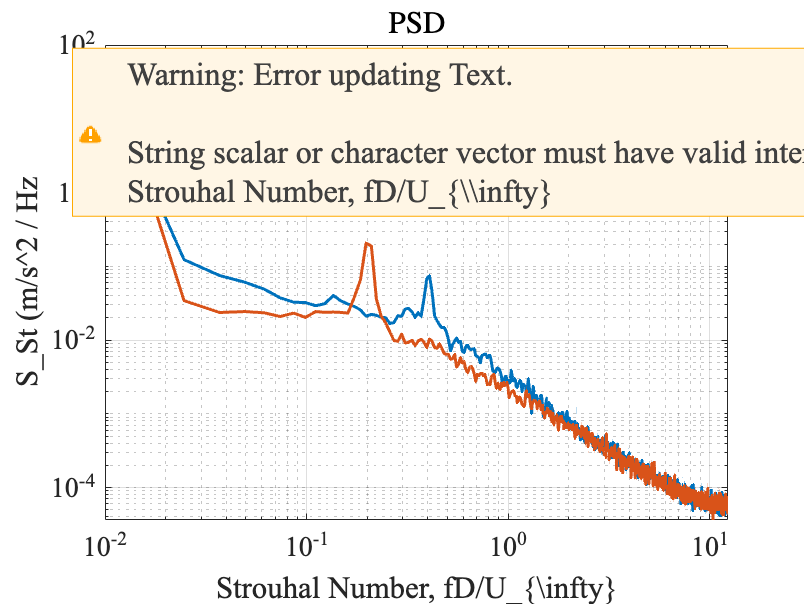

set(h,'fontSize',14)
xlabel('Strouhal Number, fD/U_{\infty}');
ylabel('S_St (m/s^2 / Hz');
title('PSD')
grid on
legend('Kulite 1','Kulite 2')

% Compute Strouhal number with Empirical Formula

T_bar = (T_amb1 + T_amb2) / 2

T_bar = 296.4500

mu = 18.29 * 10^(-6);

Re_d = (rho_bar * U_inf * d) / mu;

St_emp = 0.198 * (1 - (19.7 / Re_d))

St_emp = 0.1979